**Pregunta 6: ** Realice simulaciones del sistema utilizando los parametros establecidos enelapartado 3, por esta vez variando las posiciones iniciales en el intervalo x_0 dans [-1.5,1.5]. Emplee 20 condiciones iniciales dentro de este ramgo y represent gráficamente en el esoacio de fase las órbitas que describen la dinámica del sistema.

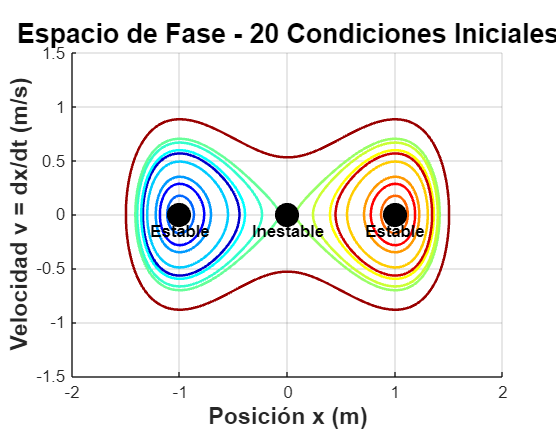

%% PREGUNTA 6: SIMULACIONES CON MÚLTIPLES CONDICIONES INICIALES

close all
clear all
clc

% Potencial de doble pozo
v = @(x) -0.5*x.^2 + 0.25*x.^4;

dVdx = @(x) -x + x.^3;

% Ecuación de movimiento: d²x/dt² = x - x³
% En forma de sistema de primer orden:
%   dx1/dt = x2
%   dx2/dt = x1 - x1³
odefun = @(t, y) [y(2); y(1) - y(1).^3];

% Parámetros de simulación (según el enunciado)
tspan = [0 100];           % Intervalo de tiempo [0, 100] s
h = 0.01;                  % Paso de integración
v0 = 0;                    % Velocidad inicial (siempre 0)

% 20 condiciones iniciales en el intervalo [-1.5, 1.5]
n_condiciones = 20;
x0_array = linspace(-1.5, 1.5, n_condiciones);

% Puntos de equilibrio del sistema
x_eq = [-1, 0, 1];

%% SIMULACIÓN PARA TODAS LAS CONDICIONES INICIALES


% Opciones para mayor precisión
opts = odeset('RelTol', 1e-6, 'AbsTol', 1e-8);

% Arrays para almacenar resultados
trayectorias = cell(n_condiciones, 1);
energias = zeros(n_condiciones, 1);

% Colores para visualización
colores = jet(n_condiciones);

% Simular cada condición inicial
for i = 1:n_condiciones
    x0 = x0_array(i);
    
    % Resolver la ecuación diferencial de Runge-Kutta de orden 4 
    [t, sol] = ode45(odefun, tspan, [x0; v0], opts);
    
    % Almacenar trayectoria
    trayectorias{i}.t = t;
    trayectorias{i}.x = sol(:, 1);
    trayectorias{i}.v = sol(:, 2);
    
    % Calcular energía inicial
    E_cin = 0.5 * v0^2;
    E_pot = v(x0);
    energias(i) = E_cin + E_pot;
end

%% GRÁFICA 1: ESPACIO DE FASE COMPLETO (20 TRAYECTORIAS)
figure('Position', [100, 100, 1000, 800]);
hold on;

% Graficar todas las trayectorias
for i = 1:n_condiciones
    plot(trayectorias{i}.x, trayectorias{i}.v, ...
         'Color', colores(i, :), 'LineWidth', 1.5);
end

% Marcar puntos de equilibrio
plot(x_eq, [0, 0, 0], 'ko', 'MarkerSize', 14, 'MarkerFaceColor', 'black');

% Etiquetas en los puntos de equilibrio
text(-1, -0.15, 'Estable', 'HorizontalAlignment', 'center', 'FontSize', 10, 'FontWeight', 'bold');
text(0, -0.15, 'Inestable', 'HorizontalAlignment', 'center', 'FontSize', 10, 'FontWeight', 'bold');
text(1, -0.15, 'Estable', 'HorizontalAlignment', 'center', 'FontSize', 10, 'FontWeight', 'bold');

% Configuración de la gráfica
xlabel('Posición x (m)', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Velocidad v = dx/dt (m/s)', 'FontSize', 14, 'FontWeight', 'bold');
title('Espacio de Fase - 20 Condiciones Iniciales', 'FontSize', 16, 'FontWeight', 'bold');
grid on;
axis equal;
xlim([-2, 2]);
ylim([-1.5, 1.5]);
hold off;

**Pregunta 7:**

function dydt = doble_pozo_general_ode(t, y, a, b)
    
    dydt = zeros(2, 1);
    
    % Ecuación 1: dx/dt = v
    dydt(1) = y(2);
    
    % Ecuación 2: dv/dt = 2bx - 4ax^3
    dydt(2) = 2*b*y(1) - 4*a*y(1)^3;
end

% --- Script Principal para el Análisis Paramétrico (Pregunta 7) ---
clc;
clear;
close all;

% Definición de los casos a estudiar:

parametros = [
     0.25, 0.0;
    0.25, 0.5;   % Caso 1: Base (a=1/4, b=1/2)
    0.25, 0.25;  % Caso 2: Menor b (barrera más baja)
    0.25, 1.0;   % Caso 3: Mayor b (barrera más alta)
     0.25, 0.8;
    0.1,  0.5;   % Caso 4: Menor a (pozos más cerca, barrera más baja)
    0.5,  0.5 ;   % Caso 5: Mayor a (pozos más lejos, barrera más alta)
    1.5,  0.5 ;
];

num_casos = size(parametros, 1);

% Inicialización de la tabla de resultados
resultados = table('Size', [num_casos, 6], ...
                   'VariableTypes', {'double', 'double', 'double', 'double', 'double', 'string'}, ...
                   'VariableNames', {'a', 'b', 'T_s', 'A_m', 'f_Hz', 'Observacion'});

% --- Parámetros de Simulación Comunes ---
tspan = [0 100];      % Intervalo de tiempo [0, 100]
x0 = -1.5;            % Posición inicial (Fija, alta energía)
v0 = 0;               % Velocidad inicial (Fija)
y0 = [x0; v0];        % Vector de condiciones iniciales



colores = lines(num_casos); % Colores para diferenciar las órbitas

for i = 1:num_casos
    a = parametros(i, 1);
    b = parametros(i, 2);
    
    % Resolución de la EDO usando ode45. 
    [t, y] = ode45(@(t, y) doble_pozo_general_ode(t, y, a, b), tspan, y0);
    
    x = y(:, 1);  % Posición
    v = y(:, 2);  % Velocidad
    
    % --- 1. Cálculo de Amplitud (A) ---
    Amplitud = max(x); 
    
    % --- 2. Cálculo del Periodo (T) ---
    [pks, locs] = findpeaks(x, t);
    
    Periodo = NaN;
    Frecuencia = NaN;
    observacion_texto = 'Movimiento Global (Entre pozos)';
    
    if length(locs) >= 2
        % T es el tiempo entre dos picos
        Periodo = locs(2) - locs(1); 
        Frecuencia = 1 / Periodo;
    else
        % Caso donde no hay suficiente oscilación (puede ser confinamiento extremo)
        observacion_texto = 'No se detecta movimiento periódico.';
    end

    % --- Chequeo de confinamiento ---
    % Si la amplitud es menor que la posición de equilibrio estable, el movimiento es raro o confinado
    x_eq_estable = sqrt(b / (2*a));
    if Amplitud < 1.0 && x_eq_estable > 0.1 % Heurística simple para detectar confinamiento
         if x_eq_estable < 1.5
             observacion_texto = 'Movimiento Confinado (Baja energía)';
         end
    end

    % Almacenar resultados
    resultados.a(i) = a;
    resultados.b(i) = b;
    resultados.T_s(i) = Periodo;
    resultados.A_m(i) = Amplitud;
    resultados.f_Hz(i) = Frecuencia;
    resultados.Observacion{i} = observacion_texto;

end



% Mostrar tabla de resultados
disp(' ');

disp('--- Tabla de Resultados del Análisis Paramétrico (Pregunta 7) ---');

--- Tabla de Resultados del Análisis Paramétrico (Pregunta 7) ---


disp(resultados);

     a       b       T_s        A_m        f_Hz                   Observacion             
    ____    ____    ______    ________    _______    _____________________________________

    0.25       0    4.8795      1.4999    0.20494    "Movimiento Global (Entre pozos)"    
    0.25     0.5    9.1865      1.5138    0.10886    "Movimiento Global (Entre pozos)"    
    0.25    0.25    5.9796      1.5184    0.16724    "Movimiento Global (Entre pozos)"    
    0.25       1    3.1603      -1.323    0.31642    "Movimiento Confinado (Baja energía)"
    0.25     0.8    3.6114    -0.96628     0.2769    "Movimiento Confinado (Baja energía)"
     0.1     0.5    4.3894        -1.5    0.22782    "Movimiento Global (Entre pozos)"    
     0.5     0.5    4.2137       1.534    0.23732    "Movimiento Gl


=== GENERANDO GRÁFICOS COMPARATIVOS ===


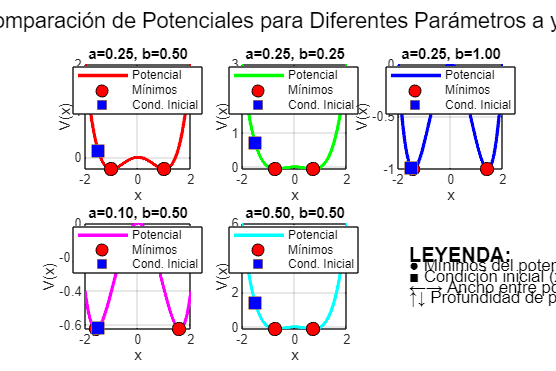

Gráficos generados. Revise la figura.



% Función para graficar los potenciales
function graficar_potenciales_comparativos()
    fprintf('\n=== GENERANDO GRÁFICOS COMPARATIVOS ===\n');
    
    parametros = [
        0.25, 0.5;
        0.25, 0.25;
        0.25, 1.0;
        0.1,  0.5;
        0.5,  0.5;
        
    ];
    
    colores = ['r', 'g', 'b', 'm', 'c'];
    x = linspace(-2, 2, 1000);
    
    figure('Position', [100, 100, 1200, 800]);
    
    for i = 1:size(parametros, 1)
        a = parametros(i, 1);
        b = parametros(i, 2);
        
        V = a*x.^4 - b*x.^2;
        
        subplot(2, 3, i);
        plot(x, V, colores(i), 'LineWidth', 2);
        hold on;
        
        % Marcar mínimos
        x_min = sqrt(b/(2*a));
        V_min = a*x_min^4 - b*x_min^2;
        plot([-x_min, x_min], [V_min, V_min], 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'red');
        
        % Marcar condición inicial
        x0 = -1.5;
        V0 = a*x0^4 - b*x0^2;
        plot(x0, V0, 's', 'MarkerSize', 10, 'MarkerFaceColor', 'blue');
        
        title(sprintf('a=%.2f, b=%.2f', a, b));
        xlabel('x');
        ylabel('V(x)');
        grid on;
        legend('Potencial', 'Mínimos', 'Cond. Inicial', 'Location', 'best');
    end
    
    subplot(2, 3, 6);
    % Leyenda explicativa
    text(0.1, 0.7, 'LEYENDA:', 'FontSize', 12, 'FontWeight', 'bold');
    text(0.1, 0.6, '● Mínimos del potencial', 'FontSize', 10);
    text(0.1, 0.5, '■ Condición inicial (x₀=-1.5)', 'FontSize', 10);
    text(0.1, 0.4, '←→ Ancho entre pozos', 'FontSize', 10);
    text(0.1, 0.3, '↑↓ Profundidad de pozos', 'FontSize', 10);
    axis off;
    
    sgtitle('Comparación de Potenciales para Diferentes Parámetros a y b');
    
    fprintf('Gráficos generados. Revise la figura.\n');
end
graficar_potenciales_comparativos();